# Modulate Audio 

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports and preprocesses the audio file.

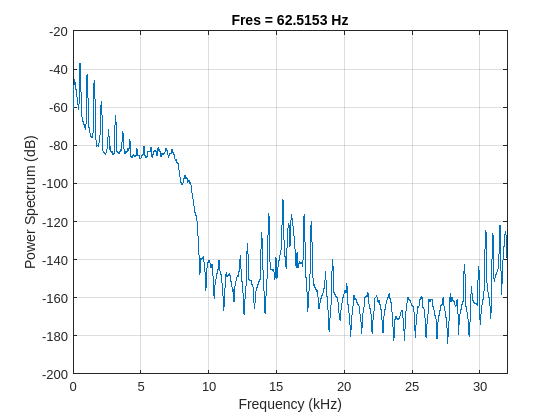

[flute, fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:7*fs);
fluteup = resample(flute, 4, 1);
fsup = fs*4;
n = numel(fluteup);
pspectrum(fluteup ,fsup)

This code imports and resamples the watermark. 

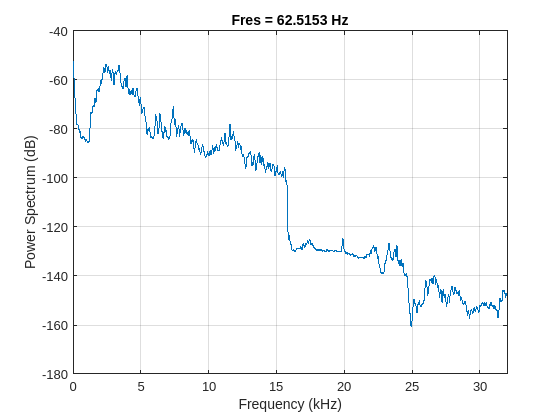

[birds, fsb] = audioread("./data/bird-call-in-spring.mp3");
birds = mean(birds, 2);
birdsdown = resample(birds, 640, 441);
birdsdown = birdsdown(1:n);
pspectrum(birdsdown, fsup)

## Task 1

In the second spectrum plot, you can see that most of the frequency content from the bird calls is between 1 kHz and 6 kHz. Before you modulate the signal, you can bandpass filter to limit the frequency range.

`sigfilt` `=` `bandpass``(``sig``,``[``f1` `f2``]``,``fs``)`

bfilt = bandpass(birdsdown, [1000 6000], fsup);

## Task 2

Next, you need to choose how you want to modify the frequency of your signal. You can do this by specifying the carrier frequency *f**c* to use while modulating. The frequency content will be shifted by *f**c*.

Recall that the original flute signal only had frequency content up to 8 kHz. The watermark's frequency goes up to 6 kHz. So the watermark should be shifted by at least 14 kHz. You can also leave a small gap between the flute and the watermark.

fc = 18000;

## Task 3

To modulate, you can use the `modulate` function:

`y` `=` `modulate``(``sig``,``fc``,``fs``)`

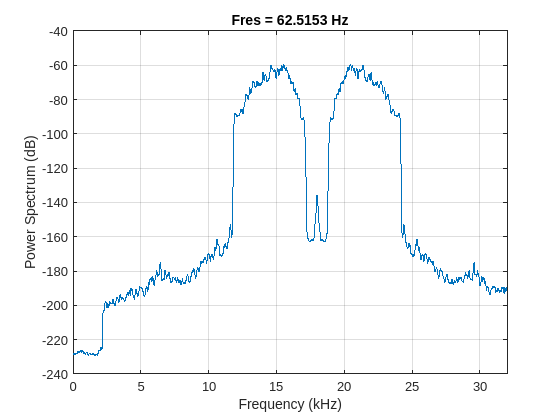

wm = modulate(bfilt, fc, fsup);
pspectrum(wm, fsup)

## Task 4

As you saw in the Task 1 **Background**, the watermark's positive and negative frequencies have been shifted to the right. That is why the watermark appears mirrored about 18 kHz.

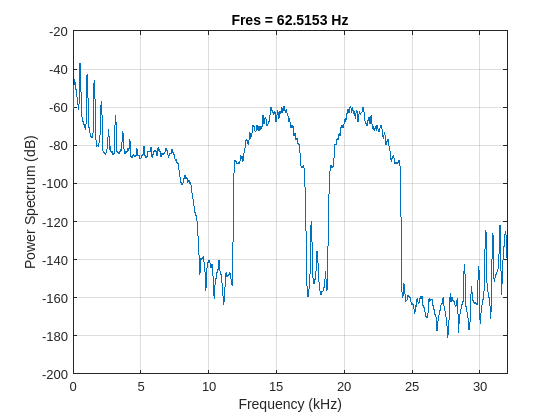

marked = wm + fluteup;
pspectrum(marked, fsup)

## Task 5

Listen to `marked` and adjust the magnitude of `wm` until you can see the watermark in the spectrum, but you can't hear the birds.

`soundsc``(``marked``,``fsup``)`

When you're ready, you can export the watermarked audio.

`audiowrite``(``"``filename``"``,``sig``,``fs``)`

audiowrite("./data/MarkedFlute.wav", marked, fsup)